## Report Part:

In this report, I will write all my analysis with graphs altogether before the code part. You can find justifications and comments on each code section as well. The code parts are at the very end of this report.

a,b,c) In this question, I will use dataset1 and strategy 1 to estimate the predictive distribution formula: Px|T(x|D1). Firstly, the class-conditional covariance is calculated using Dataset1 samples for each class. Then, by using the formula which drived in class:

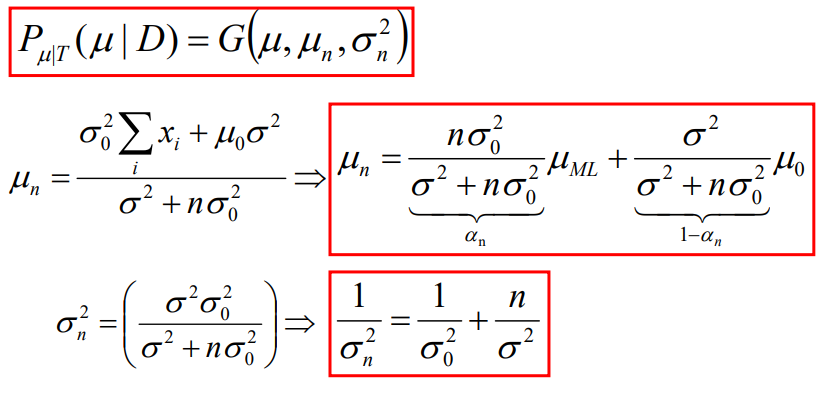

 I can calculate the posterior mean and covariance after plug into each alpha. Finally, the parameters for predictive distrinbutions are:

P X `T (x|` D) = G (x, µn, sig^2 + σ n^2). For each parameters (ML, predictive, MAP), the error curve shows that the error tend to increase and finally become stable when alpha increase. The predictive distribution tend to converge to distribution using ML estimator when alpha is larger than 0.1. When alpha is small, we can see the piror becomes an important factor to estimate the prob distribution, and this importance decrease with increasing alpha. However the ML parametors do not rely on the prior and thus stay unchanged with increasing alpha.

 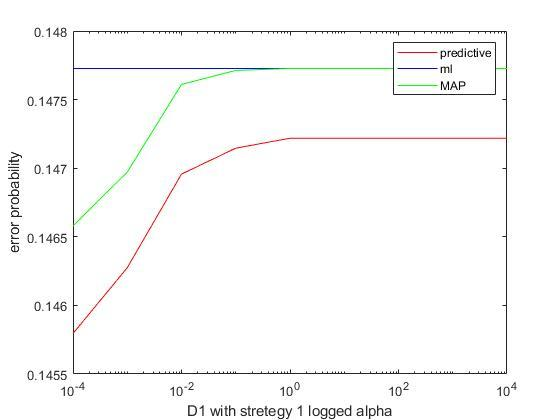

d) Repeat the above analysis using all the data sets: We can see when the dataset's size getting larger, the error of probability will decrease. For each datasize we can see the analysis above still holds, which says the  predictive will eventually converge to ML when alpha is large enough. However we can notice the MAP also converge to ML when datasize is large. This is because when the data is sufficiently large, the more distribution converge to the mean and therefore other information does not matter too much.

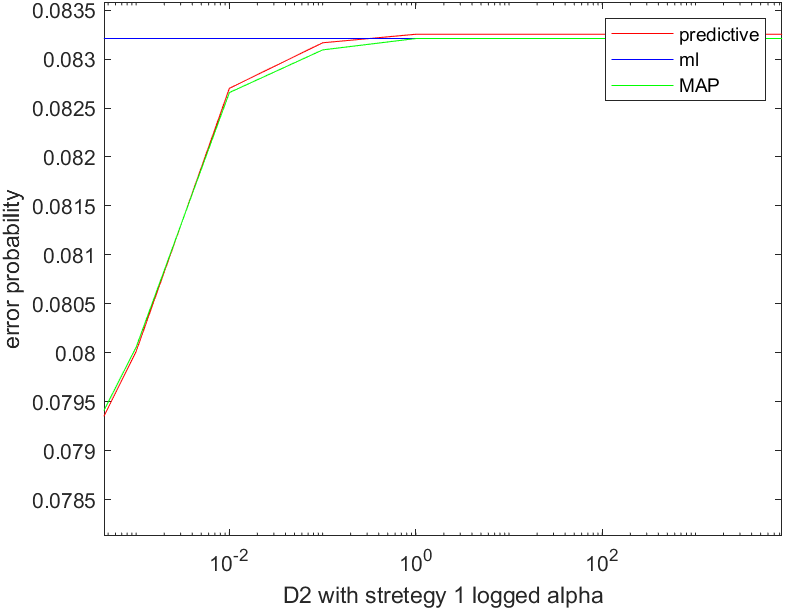

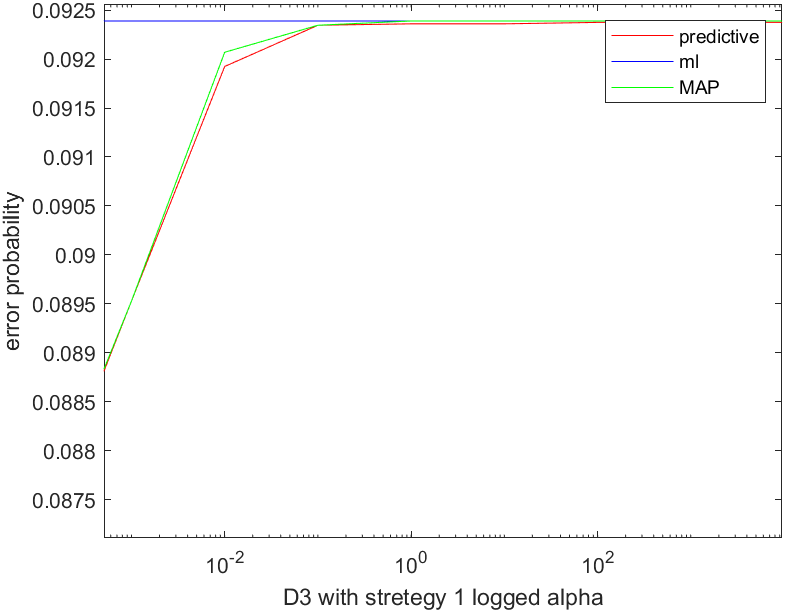

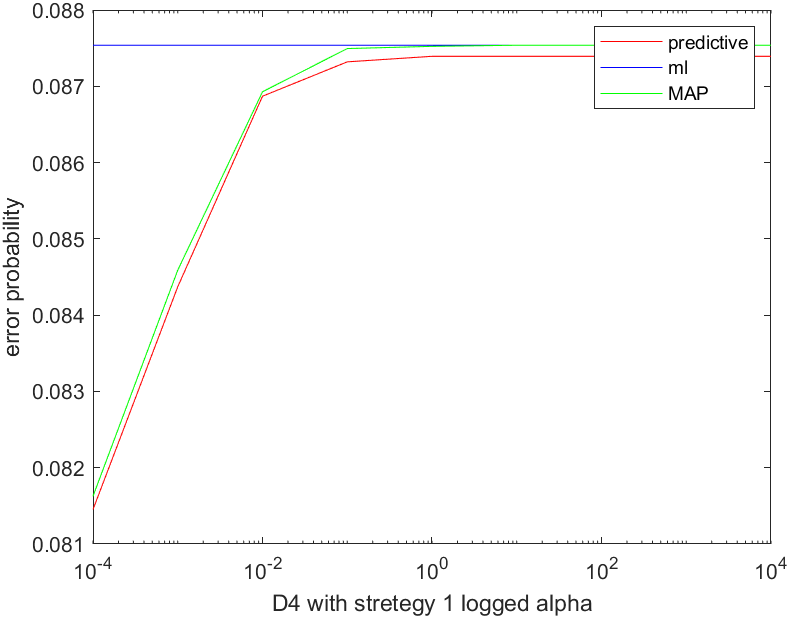

e) Now apply strategy 2 on each Dataset: Because the prior we assume is inaccurate, our result is not as good as strategy 1. With the first dataset, the piror takes an important role on classifier, therefore the predictive error and MAP is high, and the ML remain the same. As the dataset grows larger, the piror gradually become less important, therefore the accuracy goes up. The ML solution which does not depend on the piror does not change with alpha but the accuracy increase with increasing datasize. The same as above, both MAP and Predictive converge to ML when alpha is large enough.

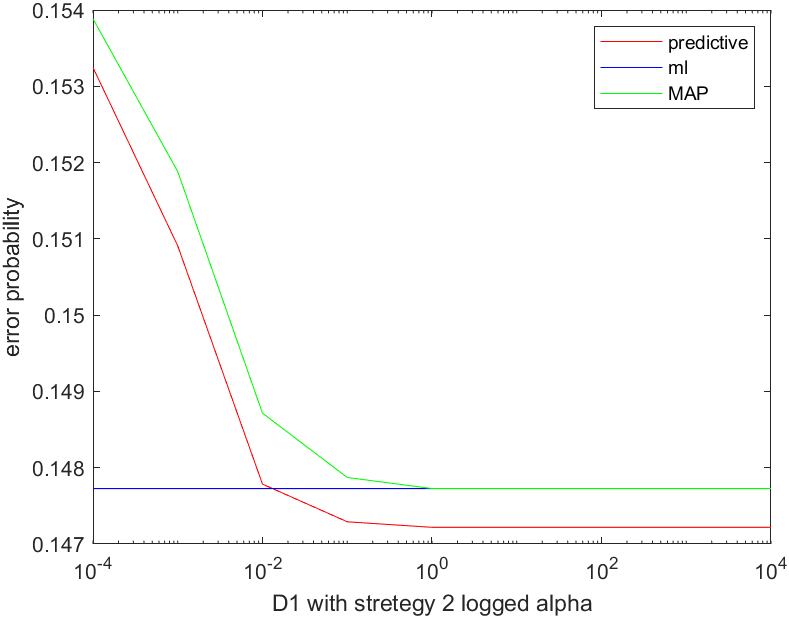

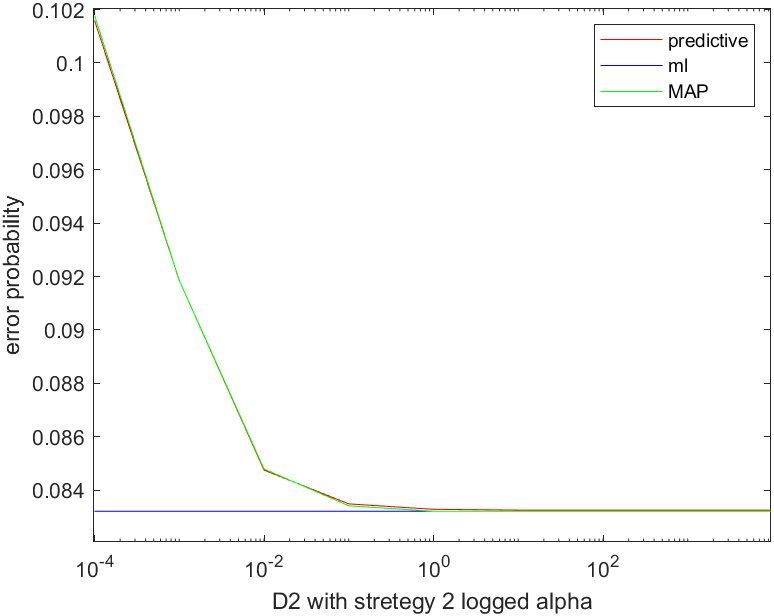

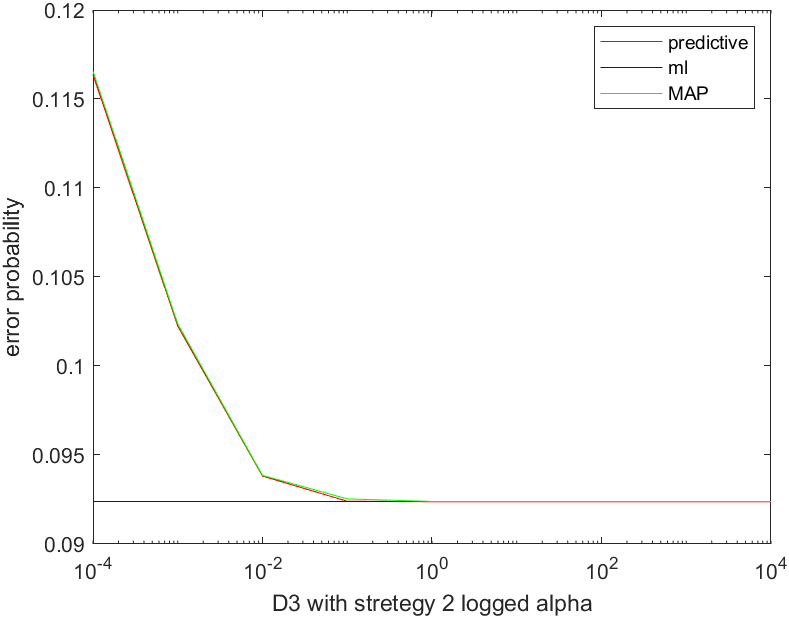

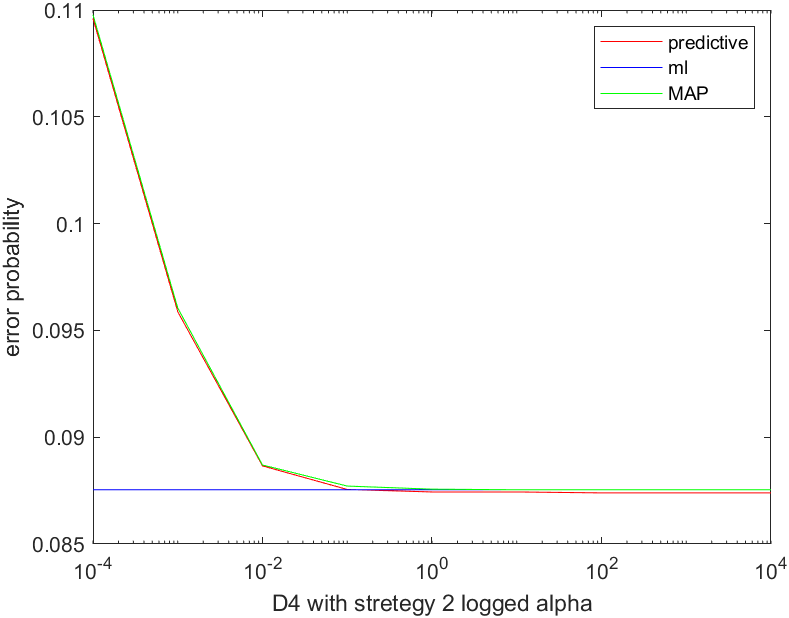

## All codes are below:

load('TrainingSamplesDCT_subsets_8.mat');
load('Prior_1.mat');
load('Prior_2.mat');
load('Alpha.mat');

%change dataset here
Db_current=D1_BG;
Df_current=D1_FG;

a) First caculate the covariance sigma of the class-conditional using D1 and according to the class note we can define the fuction to calculate u1 and sig1 and derive the parameters of the

predictive distribution.

sig_bg=cov(Db_current);
sig_fg=cov(Df_current);


n_bg=size(Db_current,1);
n_fg=size(Df_current,1);
    
ubg_ml=transpose(sum(Db_current)/n_bg);
ufg_ml=transpose(sum(Df_current)/n_fg);

mu0_BG=transpose(mu0_BG);
mu0_FG=transpose(mu0_FG);

error_pre=zeros(9,1);

%plug in each alpha
for k=1:9
    %calculate the posterior u1 and sig1
    sig0=diag(alpha(k)*W0);

    %calculate posterior u1 and sig1
    [u1_bg,sig1_bg]=calculate_u1_sig1(sig0,mu0_BG,ubg_ml,n_bg,sig_bg);
    [u1_fg,sig1_fg]=calculate_u1_sig1(sig0,mu0_FG,ufg_ml,n_fg,sig_fg);
    
    %parameters for the predictive distribution are
    upd_fg=u1_fg;
    upd_bg=u1_bg;
    
    sigpd_fg=sig1_fg+sig_fg;
    sigpd_bg=sig1_bg+sig_bg;
    
    %class priors
    p_fg=n_fg/(n_fg+n_bg);
    p_bg=n_bg/(n_fg+n_bg);
    
    I=imread('cheetah.bmp');
    I=im2double(I);
    A_pre= zeros(255,270);
    for j=1:248
        for i=1:263
            each = I(j:j+7,i:i+7);
            each = dct2(each);
            each = zigzag_scan(each);
            if joint_gaussian(each,upd_fg,sigpd_fg,p_fg)<=joint_gaussian(each,upd_bg,sigpd_bg,p_bg)
                A_pre(j,i)=1;
            end
        end
    end
    check=imread('cheetah_mask.bmp');
    check=im2double(check);
    error_pre(k,1) = sum(sum(xor(check, A_pre))) / (255*270);
    
end


%ML procedure
p_cheetah=p_fg;
p_grass=p_bg;


u_b_64= transpose(mean(Db_current,1));
u_f_64= transpose(mean(Df_current,1));

sig_b_64= cov(Db_current);
sig_f_64= cov(Df_current);

%convert each block into an array
I=imread('cheetah.bmp');
I=im2double(I);
A_ml= zeros(255,270);
for j=1:248
    for i=1:263
        each = I(j:j+7,i:i+7);
        each = dct2(each);
        each = zigzag_scan(each);
        if joint_gaussian(each,u_f_64,sig_f_64,p_cheetah)<joint_gaussian(each,u_b_64,sig_b_64,p_grass)
            A_ml(j,i)=1;
        end
    end
end
error_ml = ones(9,1)*(sum(sum(xor(check, A_ml))) / (255*270));

% MAP estimate
load('TrainingSamplesDCT_subsets_8.mat');
load('Prior_1.mat');
load('Prior_2.mat');
load('Alpha.mat');

Db_current=D1_BG;
Df_current=D1_FG;

sig_bg=cov(Db_current);
sig_fg=cov(Df_current);

n_bg=size(Db_current,1);
n_fg=size(Df_current,1);
    
ubg_ml=transpose(sum(Db_current)/n_bg);
ufg_ml=transpose(sum(Df_current)/n_fg);

mu0_BG=transpose(mu0_BG);
mu0_FG=transpose(mu0_FG);

error_map=zeros(9,1);

for k=1:9
    %calculate the posterior u1 and sig1
    sig0=diag(alpha(k)*W0);
    
    
    [u1_bg,sig1_bg]=calculate_u1_sig1(sig0,mu0_BG,ubg_ml,n_bg,sig_bg);
    [u1_fg,sig1_fg]=calculate_u1_sig1(sig0,mu0_FG,ufg_ml,n_fg,sig_fg);
    

    %parameters for the predictive distribution are
    upd_fg=u1_fg;
    upd_bg=u1_bg;
    
    sigpd_fg=sig_fg;
    sigpd_bg=sig_bg;
    
    %class priors
    p_fg=n_fg/(n_fg+n_bg);
    p_bg=n_bg/(n_fg+n_bg);
    
    I=imread('cheetah.bmp');
    I=im2double(I);
    A_map= zeros(255,270);
    for j=1:248
        for i=1:263
            each = I(j:j+7,i:i+7);
            each = dct2(each);
            each = zigzag_scan(each);
            if joint_gaussian(each,upd_fg,sigpd_fg,p_fg)<=joint_gaussian(each,upd_bg,sigpd_bg,p_bg)
                A_map(j,i)=1;
            end
        end
    end
    error_map(k,1) = sum(sum(xor(check, A_map))) / (255*270);
end

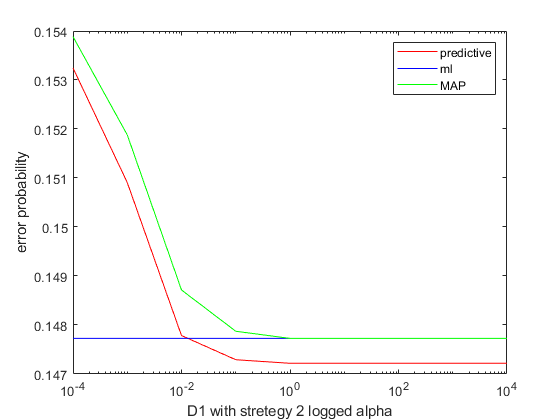


figure;
semilogx(alpha, error_pre, '-r',alpha, error_ml, '-b',  alpha, error_map, '-g' );
xlabel('D1 with stretegy 2 logged alpha');
ylabel('error probability');
legend('predictive','ml','MAP');

function [u1,sig1] = calculate_u1_sig1(sig0,u0,u_ml,n,sig)
    u1=n*sig0*inv(sig+n*sig0)*u_ml;
    u1=u1+sig*inv(sig+n*sig0)*u0;
    sig1=inv(inv(sig0)+n*inv(sig));
end

function joint_prob=joint_gaussian(x,u,sigma,prior)
    each=x.';
    d_x_y=transpose(each-u)*inv(sigma)*(each-u);
    alpha=log((2*pi)^(size(x,2))*det(sigma))-2*log(prior);
    joint_prob=d_x_y+alpha;
end

function A=zigzag_scan(m)
    ZigZagPattern=[
        0   1   5   6  14  15  27  28;
        2   4   7  13  16  26  29  42;
        3   8  12  17  25  30  41  43;
        9  11  18  24  31  40  44  53;
        10  19  23  32  39  45  52  54;
        20  22  33  38  46  51  55  60;
        21  34  37  47  50  56  59  61;
        35  36  48  49  57  58  62  63
        ];
    ZigZagPattern=ZigZagPattern+1;
    A=zeros(1,64);
    for i=1:8
        for j=1:8
            A(ZigZagPattern(i,j))=m(i,j);
        end
    end
end